Adding heterogeneity by changing the strength of agent's interactions to depend on the differences relative to other agents. The intensity of these interactions increases as agents get closer. In particular, we extend the model from Garnier:


$$d x_{j}(t)=-h U\left(x_{j}(t)\right) dt + \theta \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right) d t+\sigma d w_{j}(t)$$


where the coefficients $a_{i, j}$ quantify the strength of influence between agents $i$ and $j$. We assume that these coefficients depend only on the differences relative to other agents (and not on the positions). In particular, we assume that the coefficients are a *decreasing* function of the relative differences $|x_{i}(t) - x_{j}(t)|$.

# Setup

% Default Parameters
dt = 0.02; 
tmax = 10000;
t = 0:dt:tmax;                                 

## Threshold adjacency matrix

To start with, we assume that the adjacency matrix is of the form:


$$$$
a_{i,j}=
\begin{cases}
1, & \text{if } \quad |x_{i} - x_{j}| \leq \tau \\
0, & \text{if } \quad |x_{i} - x_{j}| > \tau
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N
$$$$


where $\tau$ denotes the 'threshold value' - the minimum distance required between $x_{i}$ and $x_{j}$ for them to continue interacting with each other.

Consider the model in Garnier and Papanicolaou, 2013, with two stable equilibria. If the threshold value is very high, then this has no effect on the model. If the threshold value is very low, then the model behaves as if there is only one equilibria; 0. This is because the mean of interactions with all samples tends towards 0 as the threshold value decreases towards 0. This has the effect of the paths reverting to the mean of the interactions, which is 0. 

I define $\tau_{c}$ as the 'critical' threshold value where this non-linear change from two stable equilibria to one occurs.

As a test, I set the threshold value to infinity. This should give the same results as the original model.


$$\tau = \infty$$
 

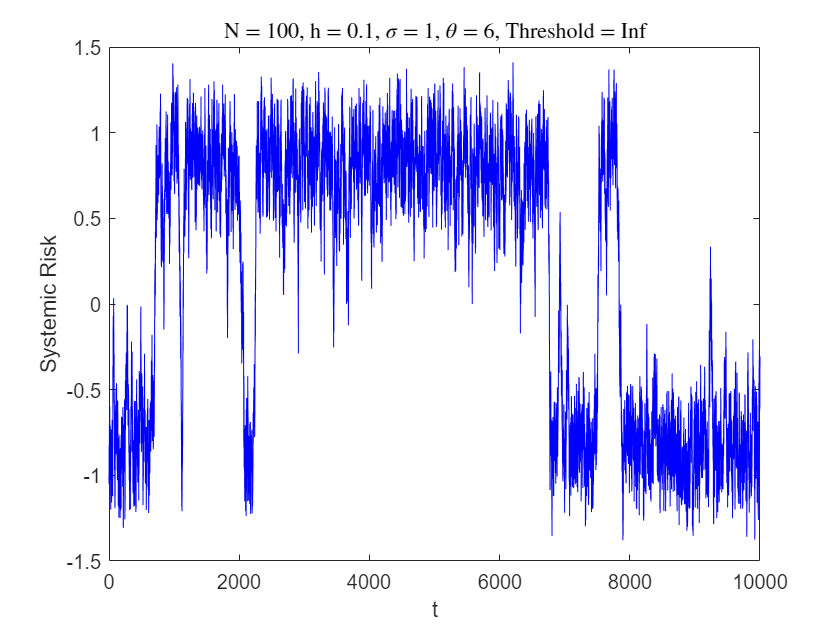

N = 100;
h = 0.1;                     
theta = 6;
sig = 1;

SolveHomogeneousSDE(t, N, h, sig, theta, inf);

### Varying $\sigma$

Simulations for different $\sigma$ = 1, 2, 4

In the original model, the system had two stable equilibria when σ was below the critical value (approximately $1$ for small $h$).

Fix $N, h, \theta$:

tmax = 10000;
t = 0:dt:tmax; 
N = 100;
h = 0.1;                     
theta = 6;
tau_low = 0.8;
tau_high = 0.9;

$\sigma = 1$:

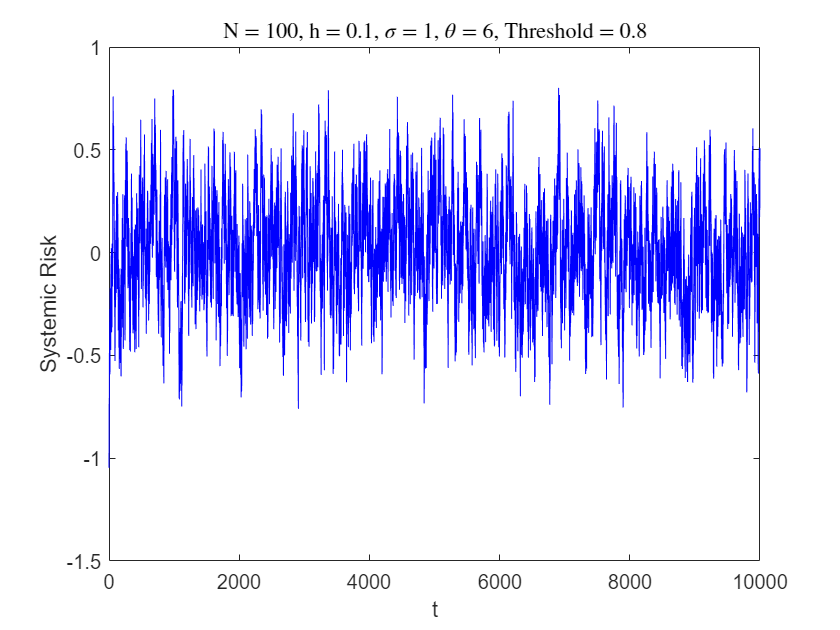

sig = 1;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

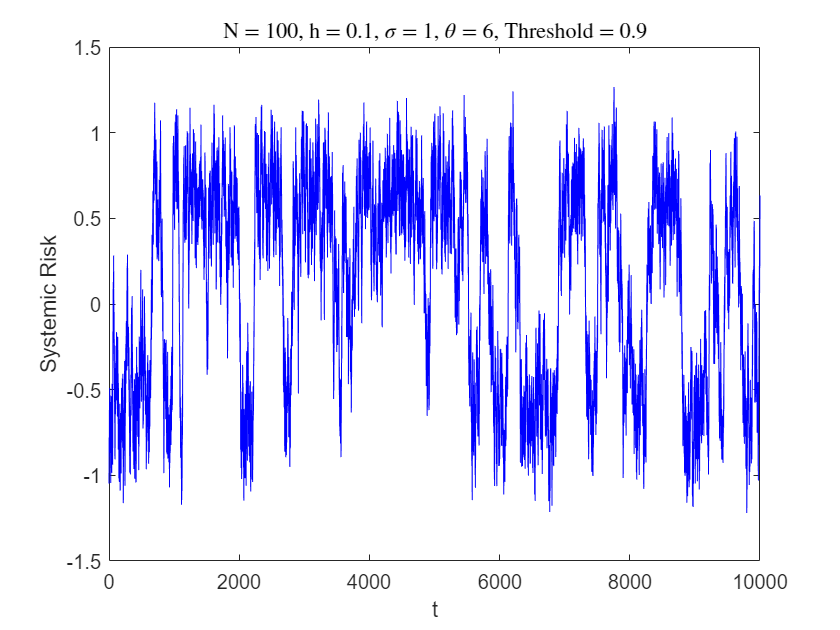

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$\sigma = 2$:

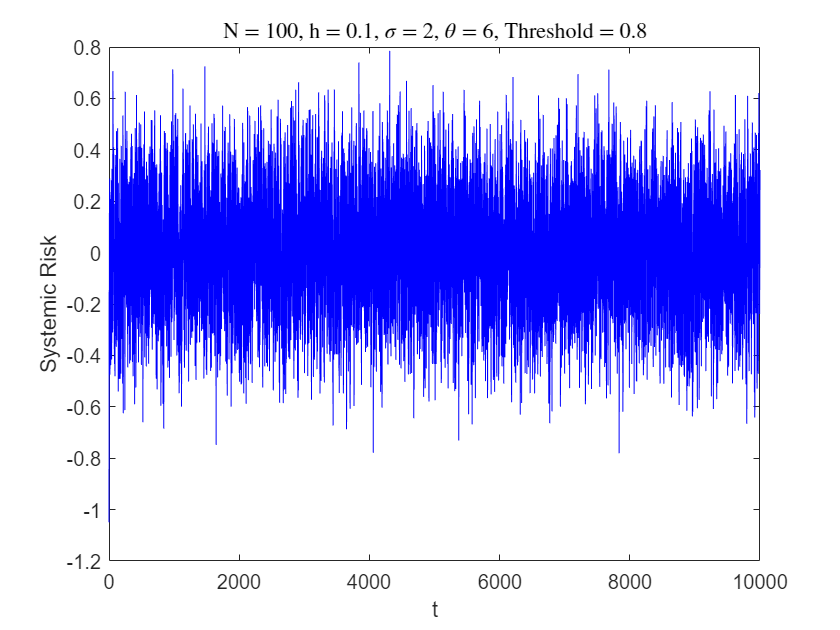

sig = 2;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

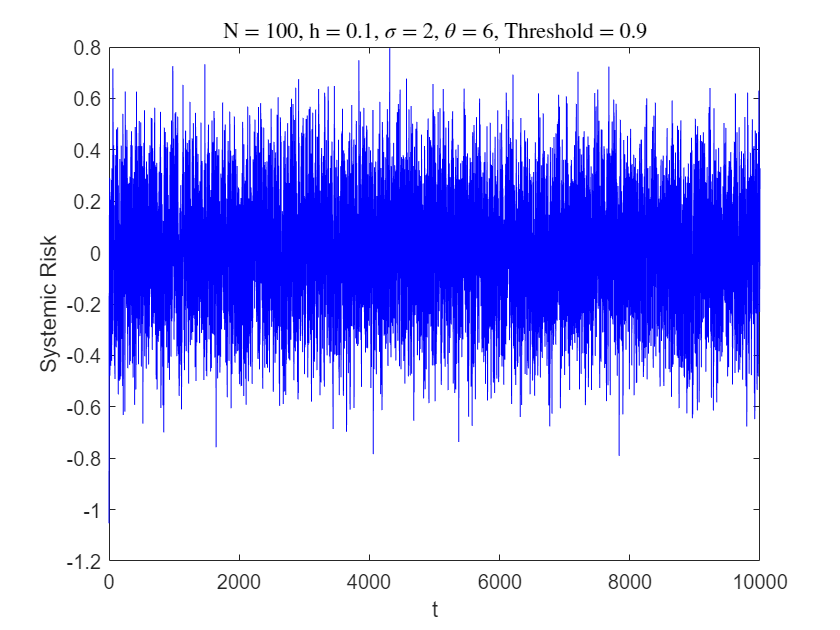

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$\sigma = 4$:

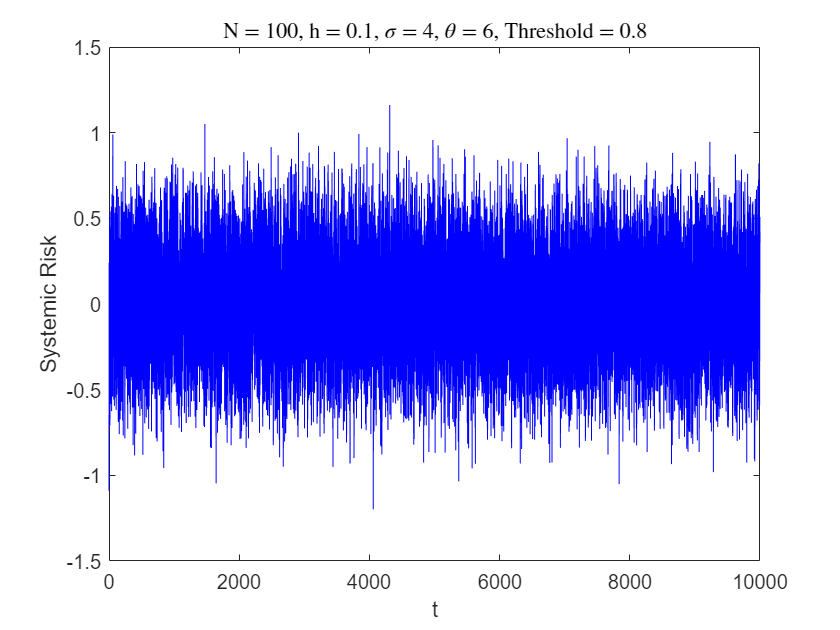

sig = 4;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

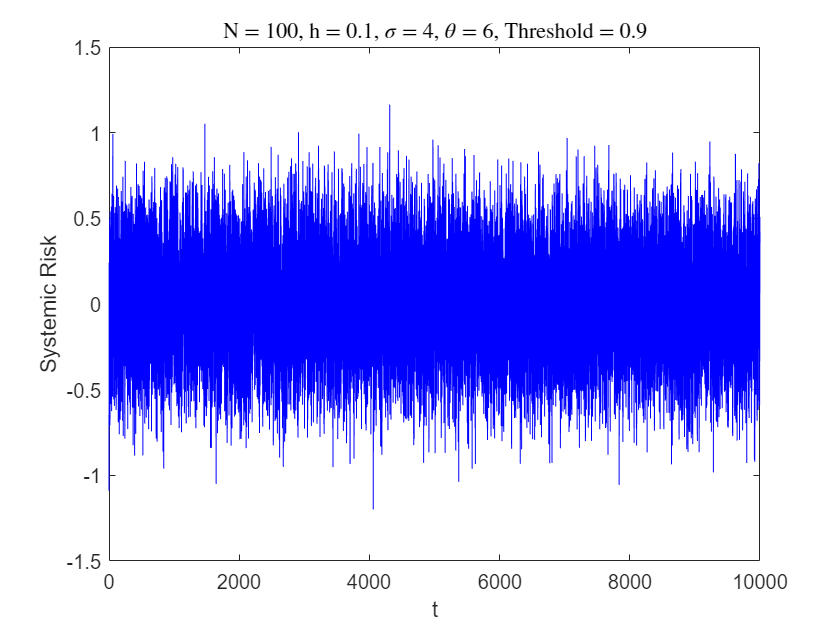

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

Conclusion: 

In the original model with two stable equilibria (when $\sigma = 1$), setting the threshold value at 0.8 causes the mean to oscillate around 0. However, when the threshold value is 0.9, the system continues to have two equilibria, but the system is less stable, as the number of times the system jumps from one equilibria to the other increases.

When there was only one stable equilibria (when $\sigma = 2, 4$), introducing a threshold does not change the fact that the mean continues to oscillate around 0. However, the variance of the oscillations are reduced.

### Varying $\theta$

Simulations for different $\theta = 5, 1.5, 0.5$

In the original model, the system had two stable equilibria if θ was above the critical value or otherwise has single stable state 0.

Fix $N, h, \sigma$:

tmax = 10000;
t = 0:dt:tmax; 
N = 100;
h = 0.1;                     
sig = 1;
tau_low = 0.9;
tau_high = 1;

$\theta = 5$:

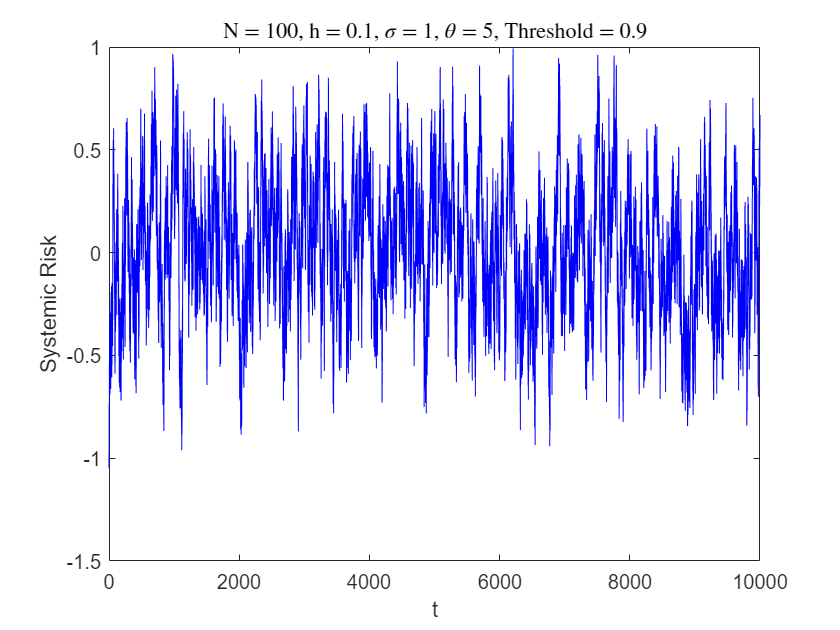

theta = 5;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

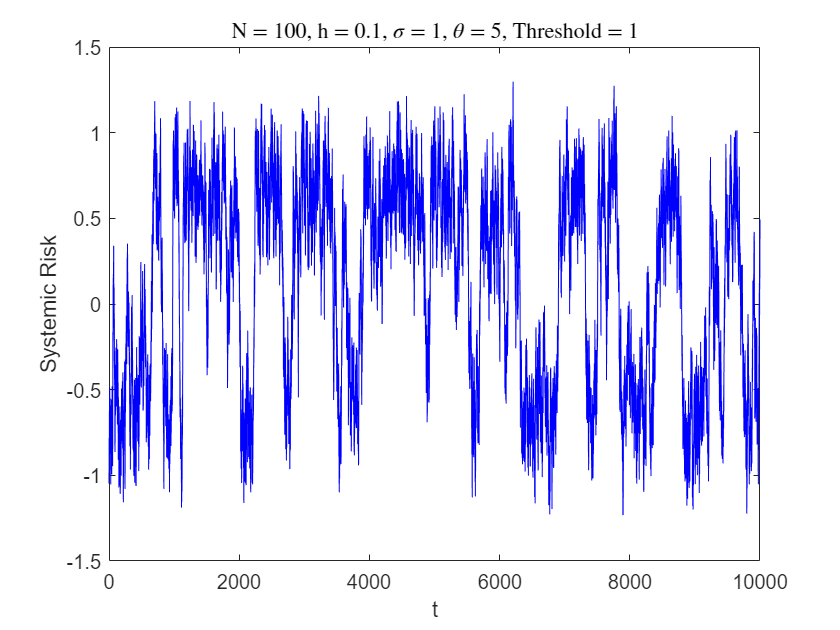

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$\theta = 1.5$:

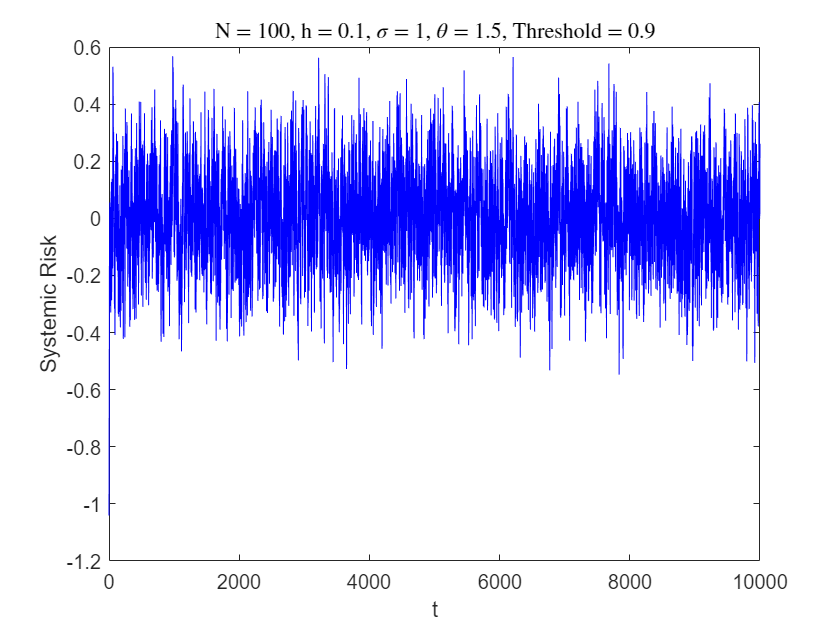

theta = 1.5;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

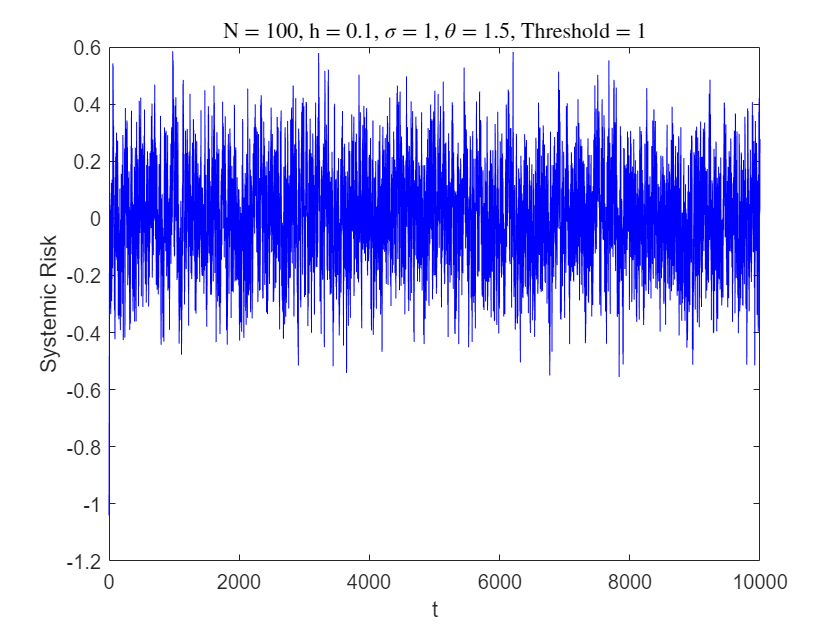

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$\theta = 0.5$:

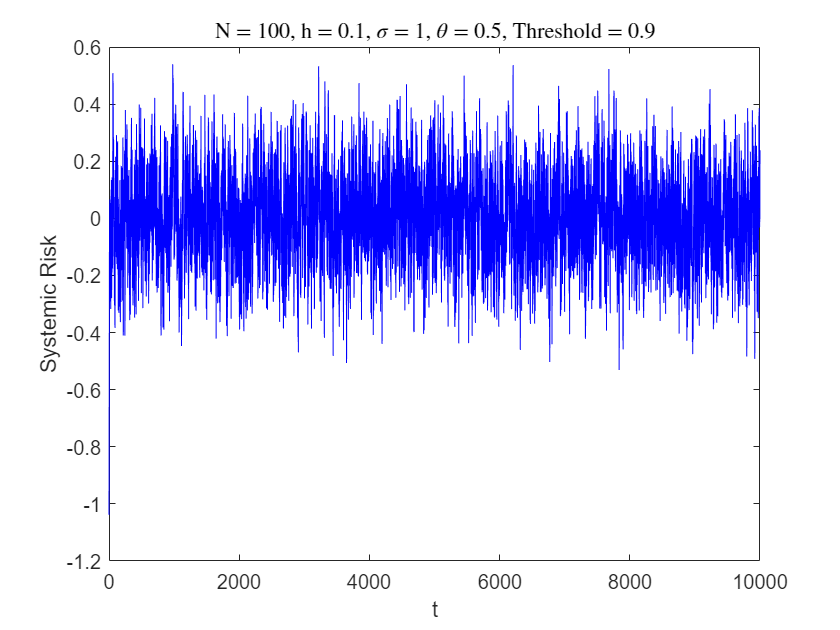

theta = 0.5;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

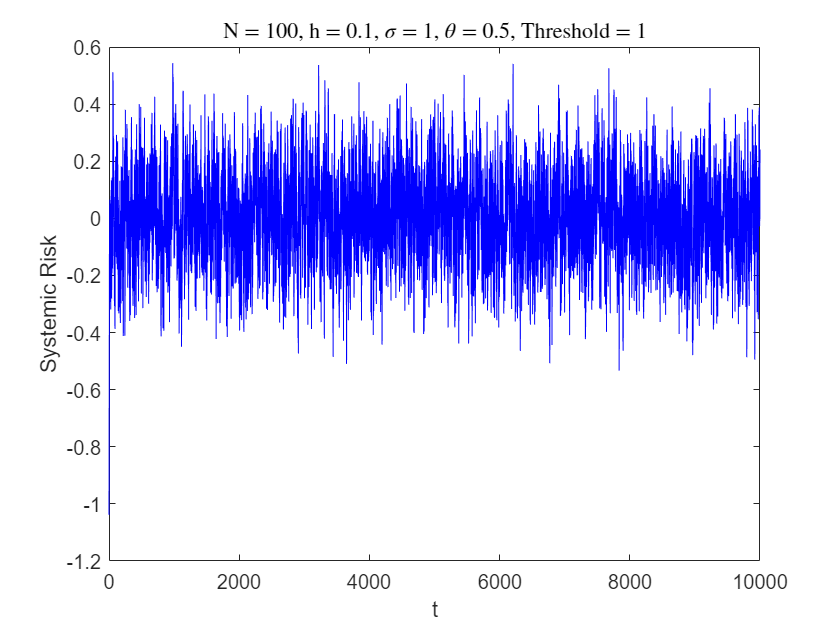

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

Conclusion:

$\theta$ measures the strength of the interactions. In the original model, when $\theta = 5$, there were two stable equilibria. When the threshold value is 0.9, there is only one equilibria, where the mean oscillates around 0. When the threshold value is 1, the mean oscillates between the original two equilibria.

Note that the critical threshold value for $\theta=5$ is between 0.9 and 1, whereas for $\theta=6$, it was between 0.8 and 0.9. A higher $\theta$ corresponds to stronger interactions, which reduces the critical threshold value.

### Varying $h$

Simulations for different $h = 0.02, 0.1, 0.5$

In the original model, increasing $h$ made the system more stable.

Fix$N, \theta, \sigma, \tau_{l}, \tau_{h}$:

tmax = 10000;
t = 0:dt:tmax; 
N = 100;
theta = 10;                     
sig = 1;
tau_low = 0.7;
tau_high = 0.8;

$h = 0.02$:

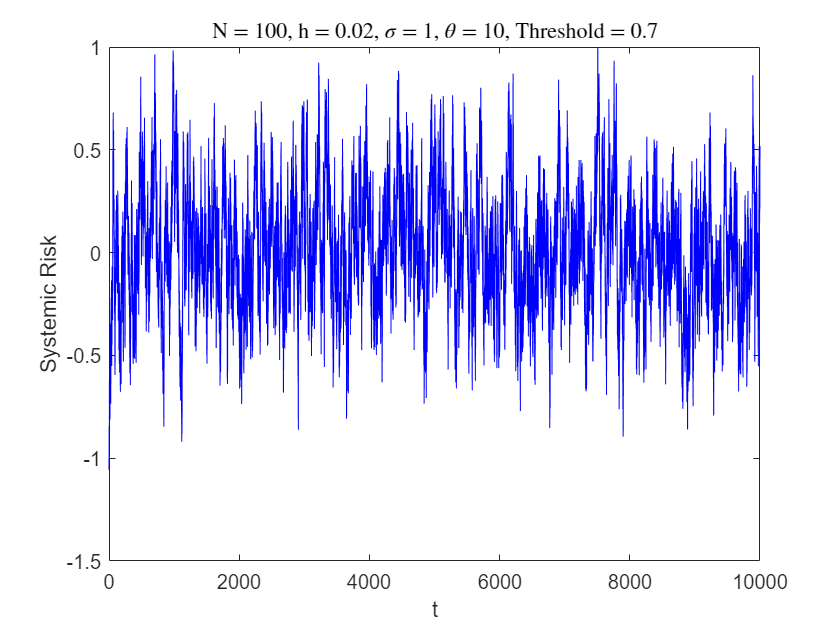

h = 0.02;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

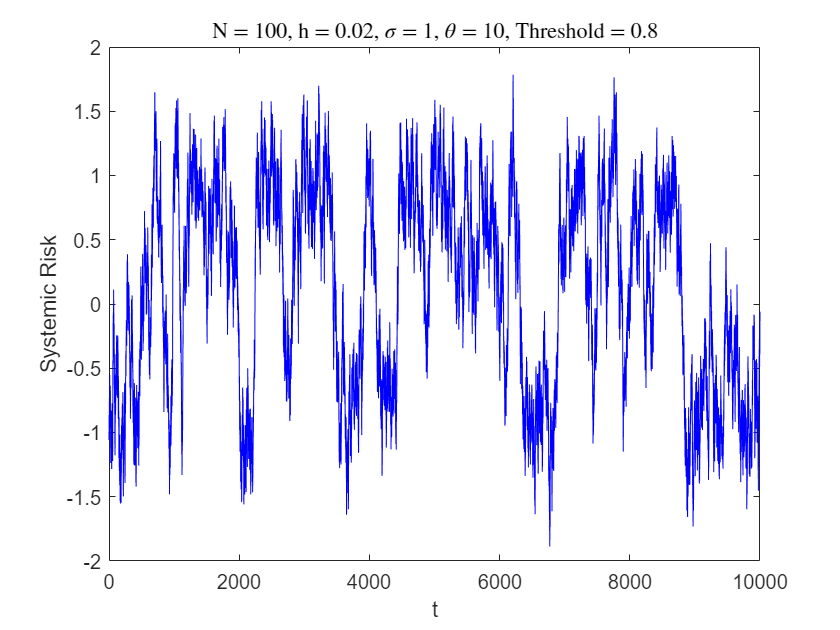

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$h = 0.1$:

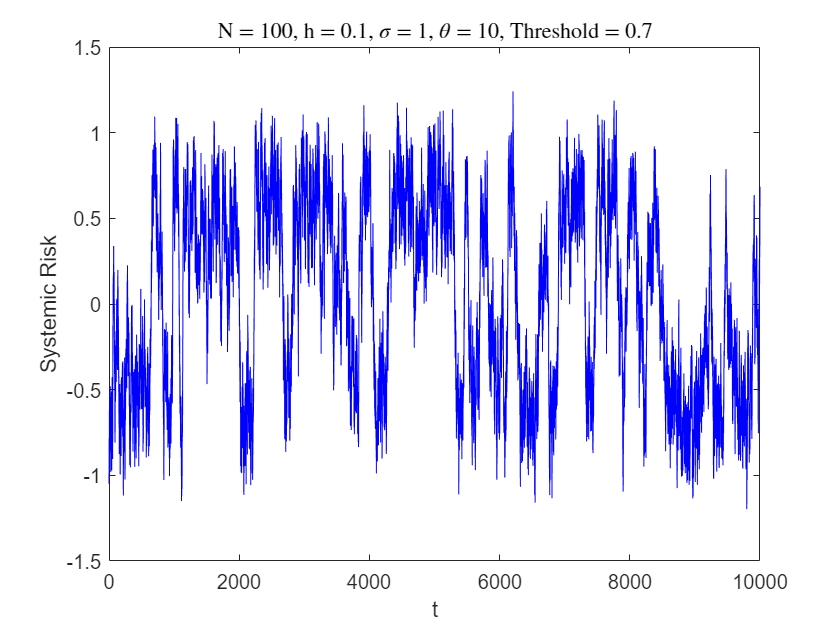

h = 0.1;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

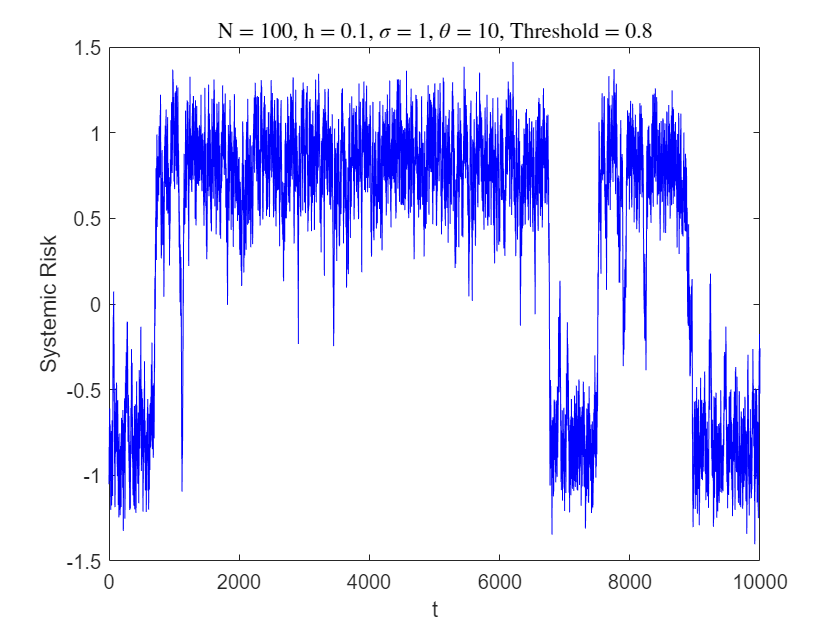

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$h = 0.5$:

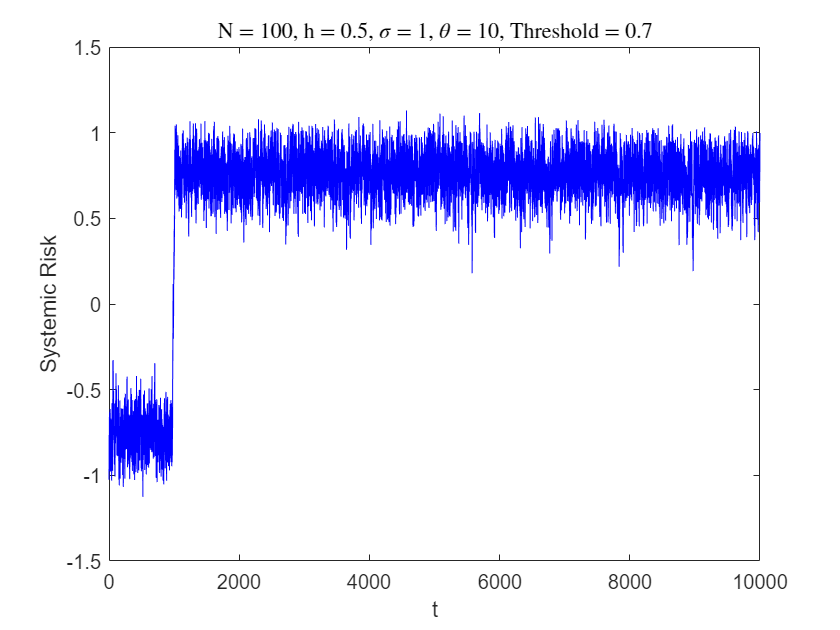

h = 0.5;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

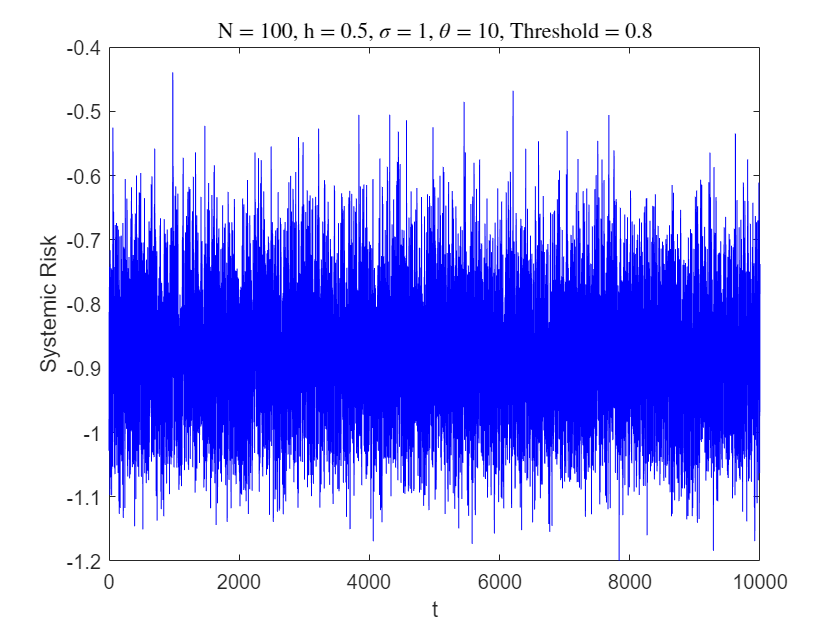

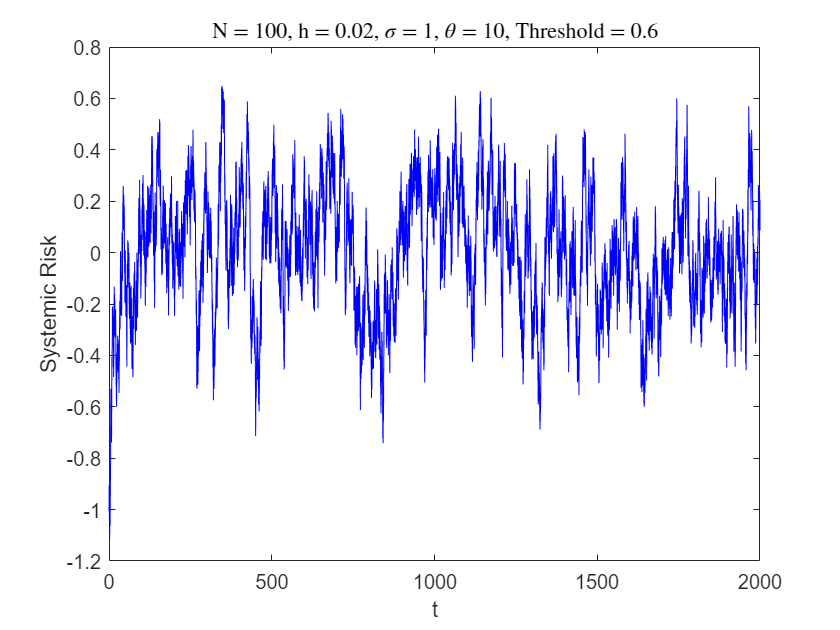

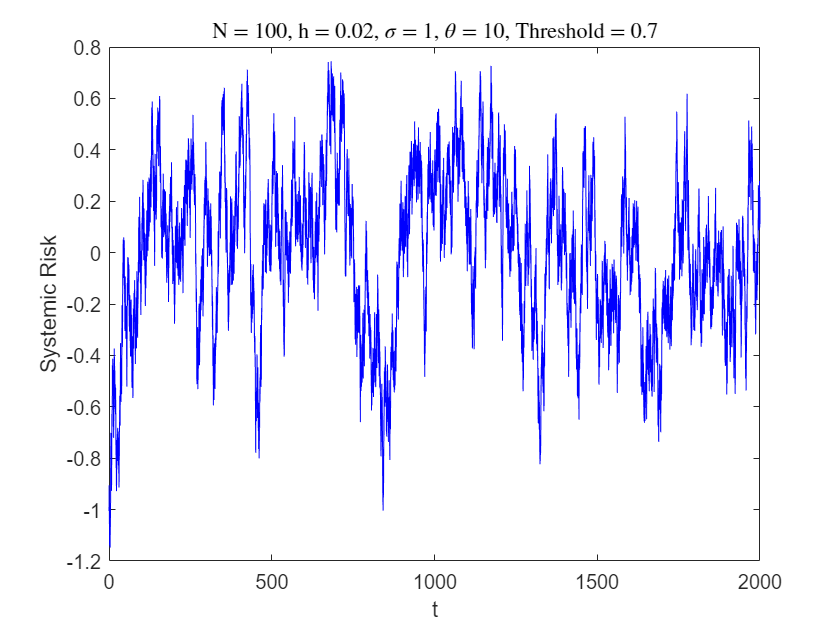

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

Conclusion:

For $h=0.02$, (when the model is less stable), the critical threshold value is between 0.7 and 0.8. Interestingly, when $h=0.5$, in the original model, the mean stayed around -1 for all $t$. Introducing a low enough threshold value makes the mean jump to the other equilibrium. This can be interpreted as destabilising the system.

### Varying $N$

Increasing $N$ tends to have more stable behaviour.

Simulations for different $N = 40, 80, 120$.

Fix $h, \sigma, \theta, \tau_{l}, \tau_{h}$:

tmax = 10000;
t = 0:dt:tmax; 
h = 0.1;
sig = 1;
theta = 10;
tau_low = 0.6;
tau_high = 0.7;

$N = 40$:

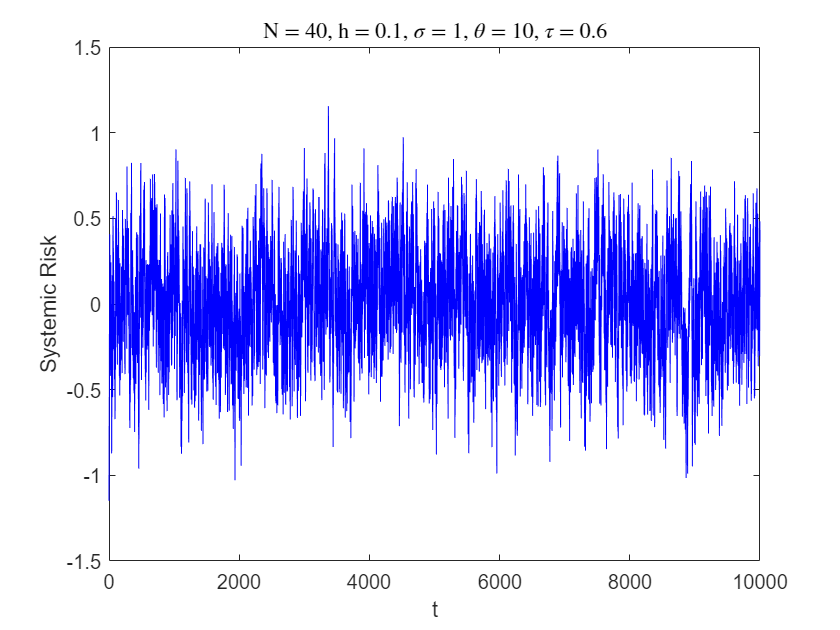

N = 40;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

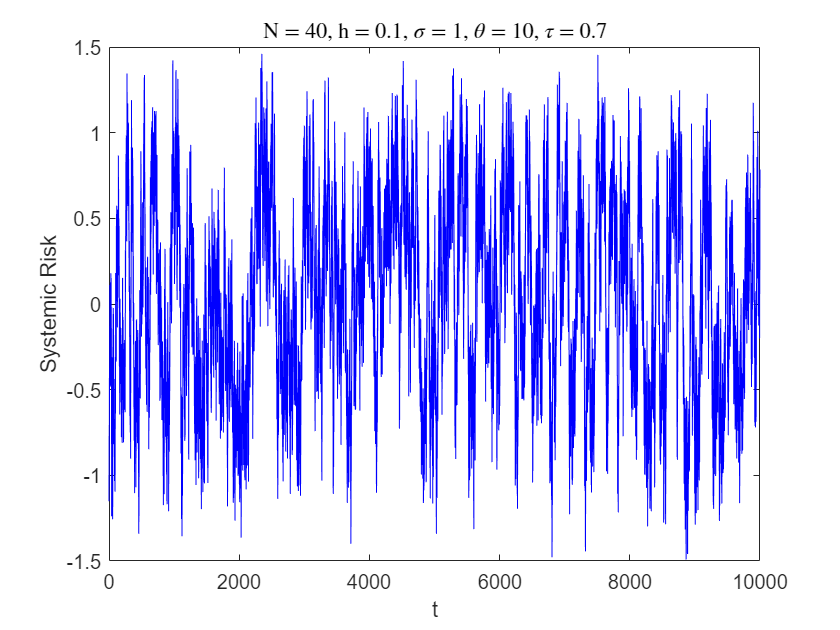

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$N = 80$:

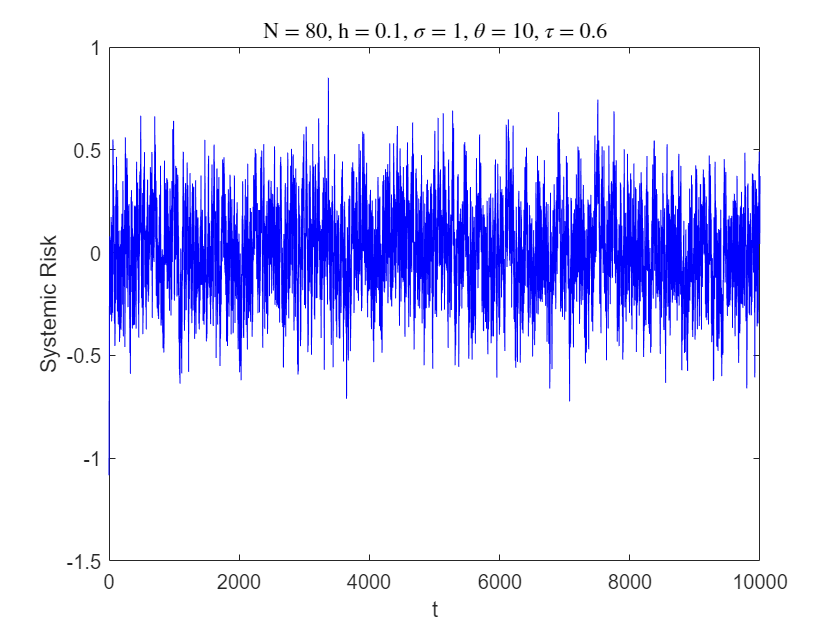

N = 80;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

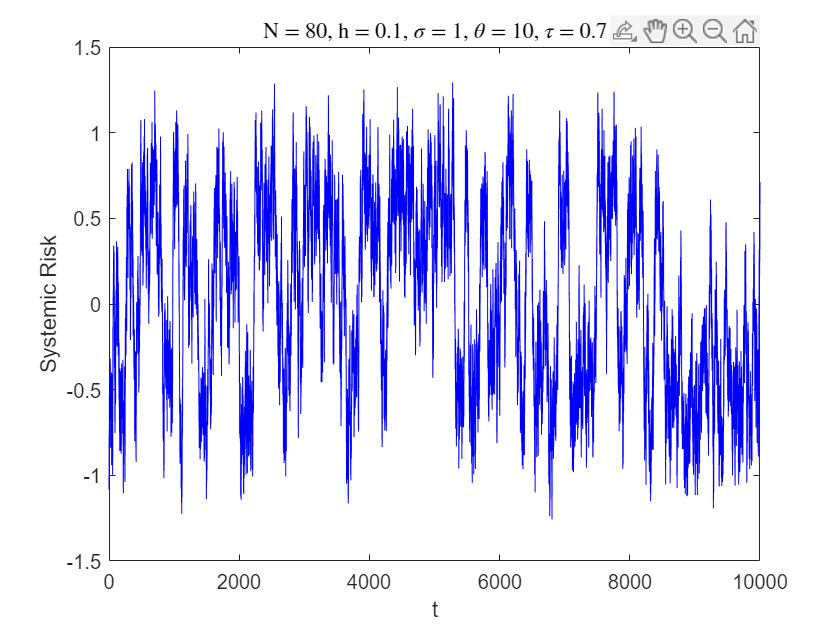

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

$N = 120$:

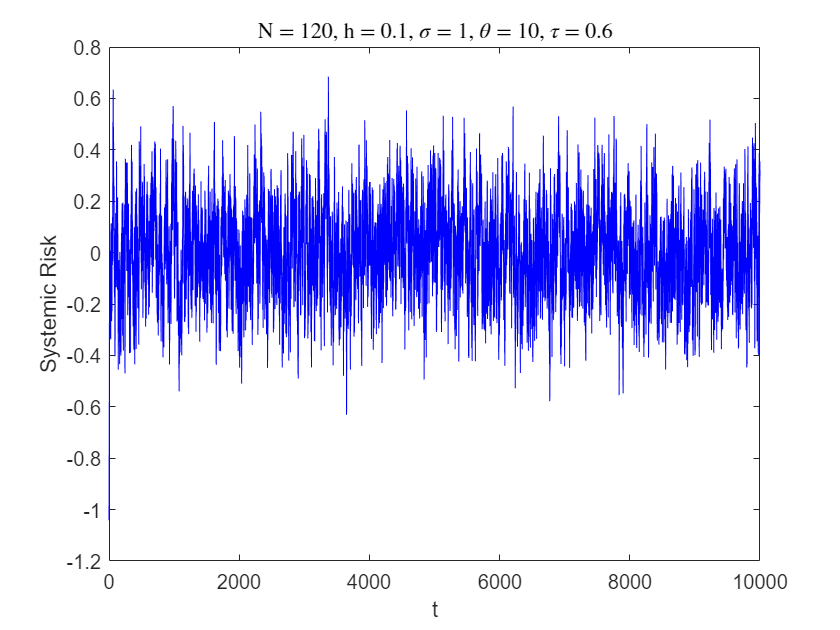

N = 120;
SolveHomogeneousSDE(t, N, h, sig, theta, tau_low);

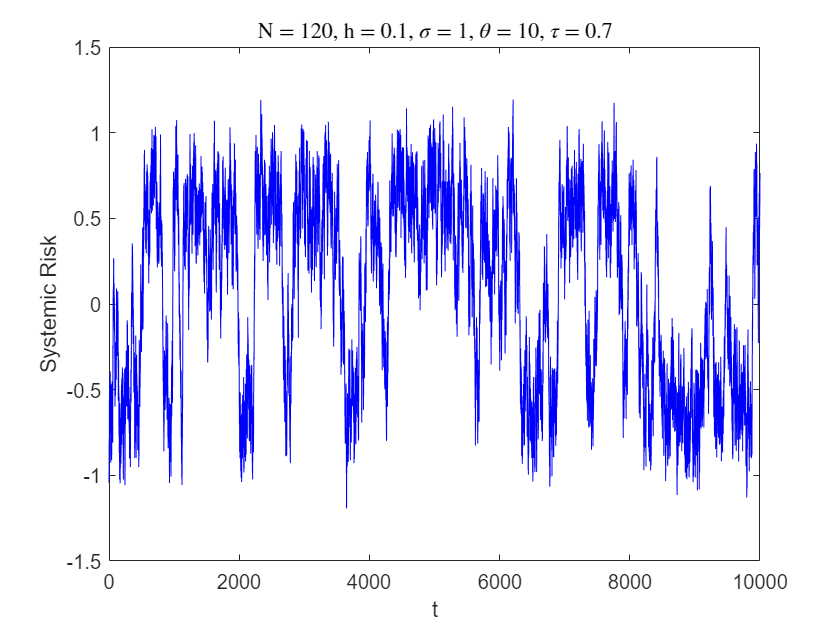

SolveHomogeneousSDE(t, N, h, sig, theta, tau_high);

Conclusion:

Increasing $N$ increases the stability of the system. However, the critical threshold value seems to be independent of $N$, as it lies between 0.6 and 0.7 for all three values of $N$.

## Heterogeneous model

We could consider the case in which each agent can have a different rate of mean reversion to the empirical mean:


$$d x_{j}(t)=-h U\left(x_{j}(t)\right) dt + \theta_{j} \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right) d t+\sigma d w_{j}(t)$$


The different values of $\theta_j$ are controlled by the parameters $\Theta_l$ and $\rho_l$.

### Effect of changes in $\sigma$

Here we take $K = 3$ and $\left\{\Theta_{l}\right\}_{l=1}^{K}=\left\{\Theta_{L}, \Theta_{M}, \Theta_{H}\right\}$for a system of low, medium, and high rates of mean reversion to the empirical mean, that is, the systemic risk. We also take $\left\{\rho_{l}\right\}_{l=1}^{K}=\left\{\rho_{L}, \rho_{M}, \rho_{H}\right\}$for the corresponding fractions.

Fix $N, h, \theta, \rho, \tau_l, \tau_h$:

tmax = 10000;
t = 0:dt:tmax; 
N = 100;
h = 0.1;

theta_l = 5; theta_m = 10; theta_h = 15;
rho_l = 0.33; rho_m = 0.34; rho_h = 0.33;

Theta = [theta_l; theta_m; theta_h];
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

tau_low = 0.6;
tau_high = 0.8;

$\sigma = 1:$ Two stable equilibria

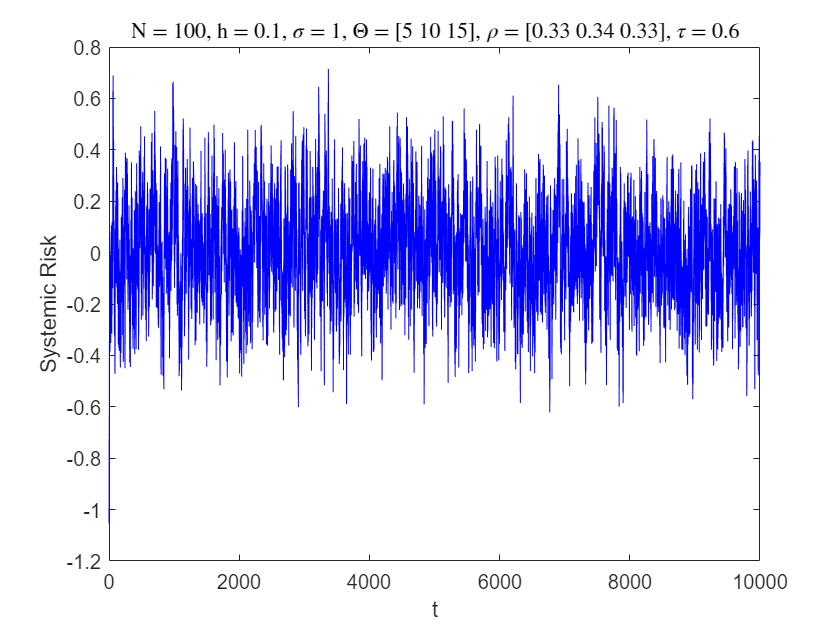

sig = 1;  
SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

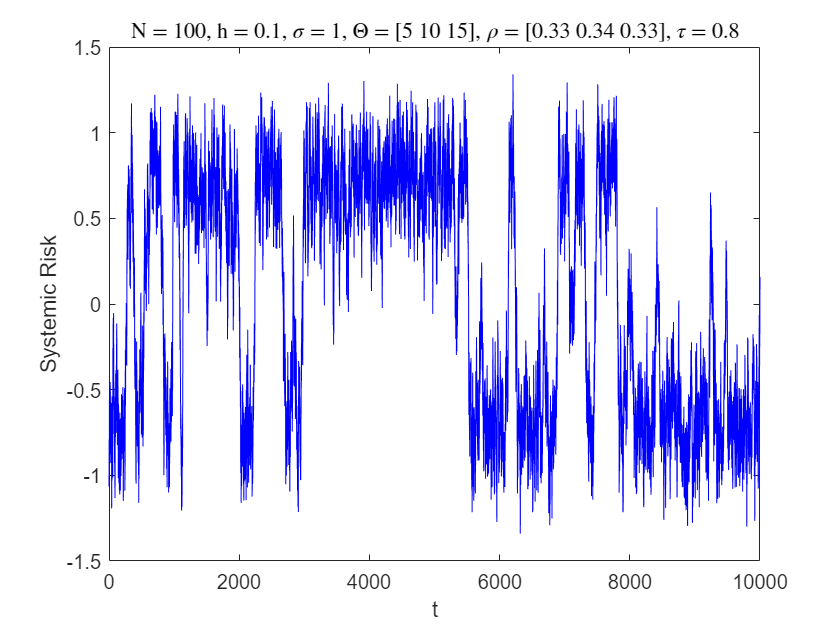

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$\sigma = 2.1218$: One/two stable equilibria.

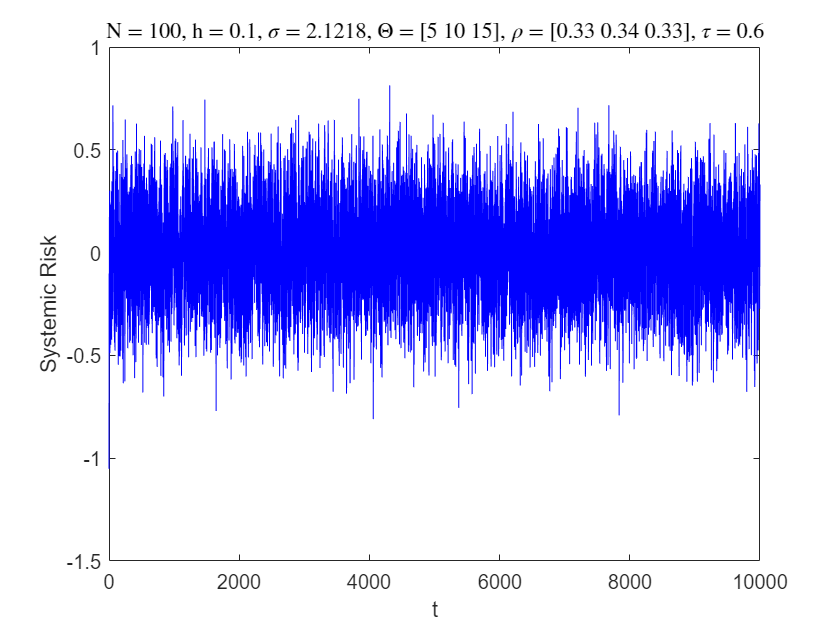

sig = 2.12175;
SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

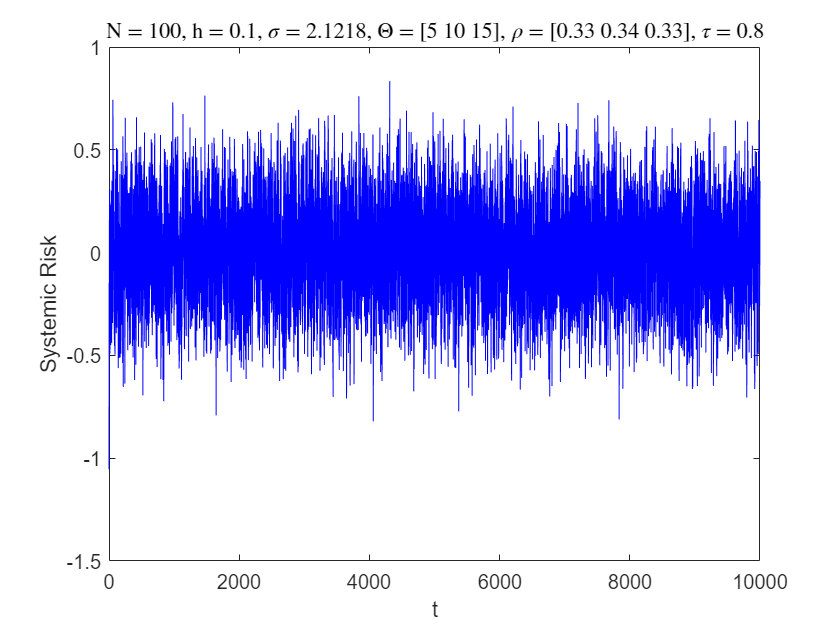

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$\sigma = 3$: One stable equilibria

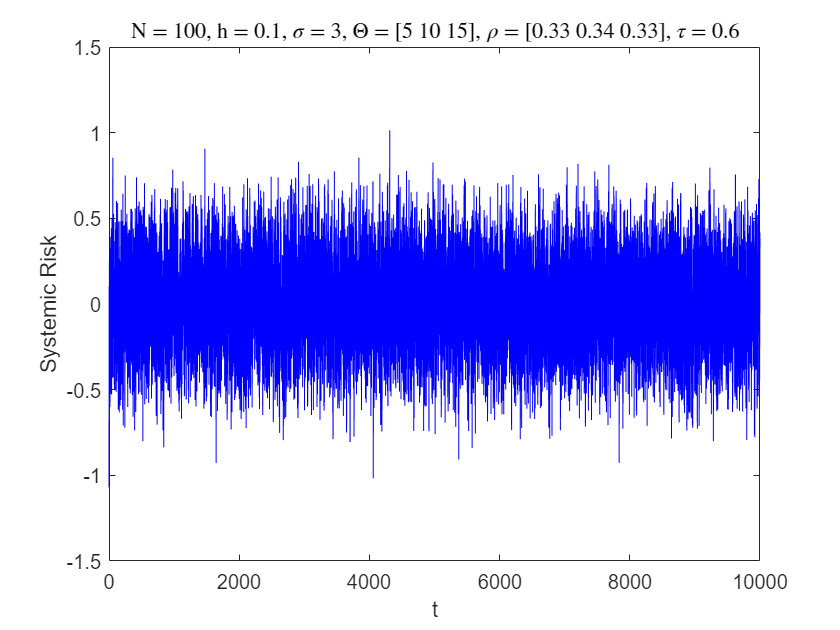

sig = 3;
SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

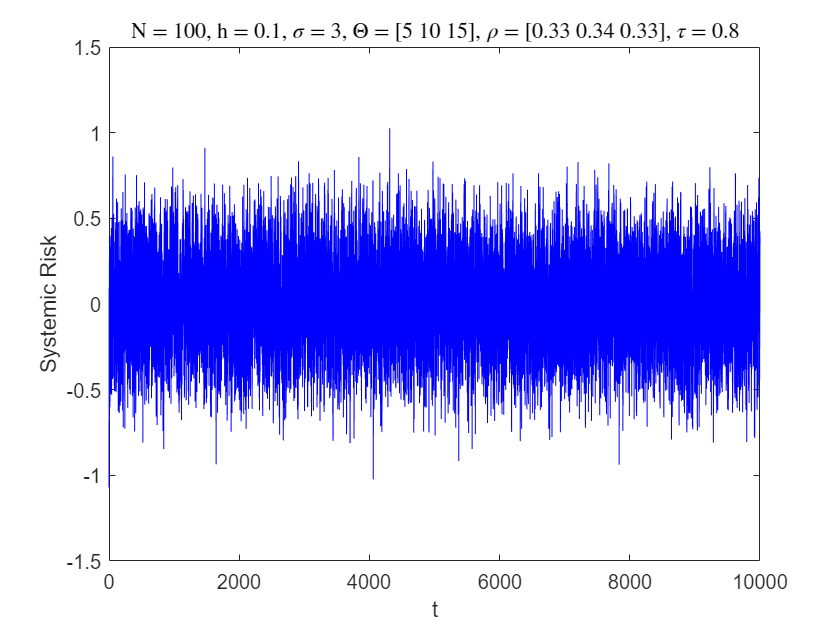

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

Conclusion: 

Similar to homogeneous case. If the threshold value is too low, then the model moves from two equilibria to one.

### Varying $h$

Simulations for different $h = 0.02, 0.1, 0.5$

Fix $N, \sigma, \Theta, \rho, \tau_l, \tau_h$:

N = 100;
sig = 1;

theta_l = 5; theta_m = 10; theta_h = 15;
rho_l = 0.33; rho_m = 0.34; rho_h = 0.33;

Theta = [theta_l; theta_m; theta_h];
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

tau_low = 0.6;
tau_high = 0.8;

$h = 0.02$:

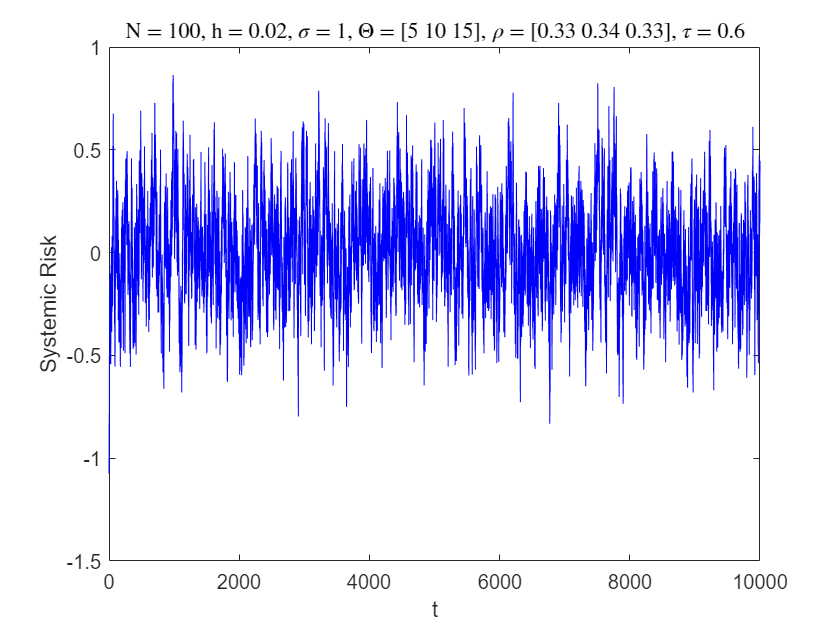

h = 0.02;
SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

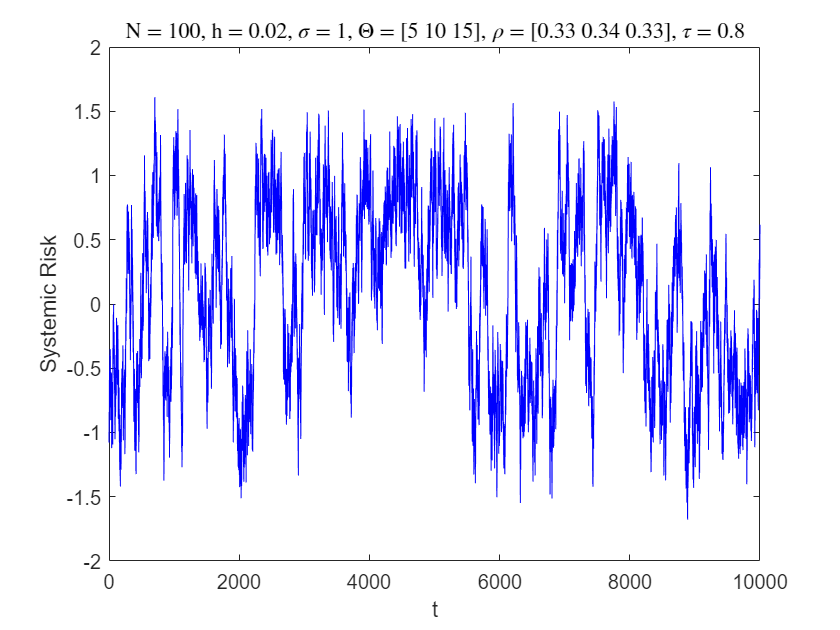

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$h = 0.1$:

h = 0.1;
SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$h = 0.5$:

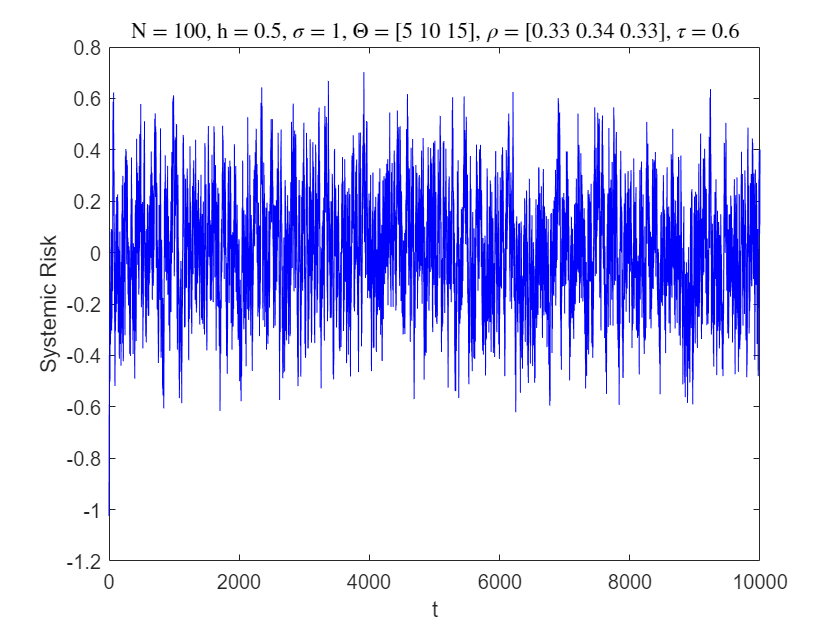

h = 0.5;
SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

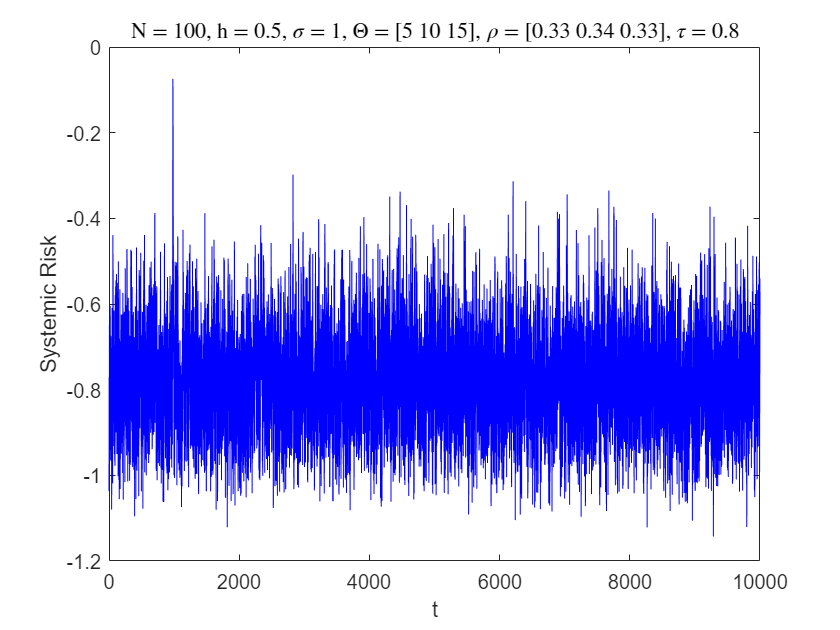

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

### Varying $N$

Increasing $N$ tends to have more stable behaviour.

Simulations for different $N = 40, 80, 120$.

Fix $h, \sigma, \Theta, \rho$:

h = 0.1;
sig = 1;

theta_l = 5; theta_m = 10; theta_h = 15;
rho_l = 1/3; rho_m = 1/3; rho_h = 1/3;

Theta = [theta_l; theta_m; theta_h];
rho = [rho_l; rho_m; rho_h];

tau_low = 0.6;
tau_high = 0.8;

$N = 80$:

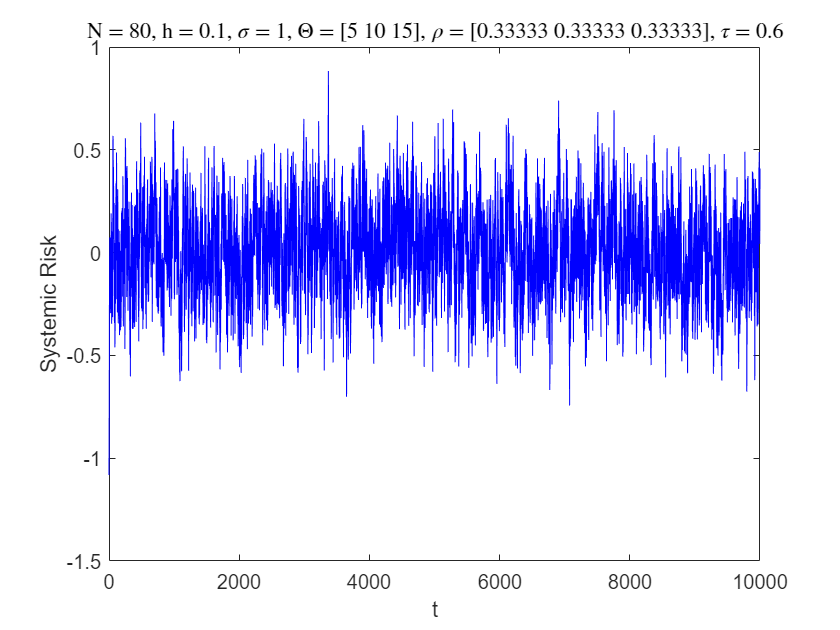

N = 80;

theta = [
    repelem(theta_l, 27, 1);
    repelem(theta_m, 27, 1);
    repelem(theta_h, 26, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

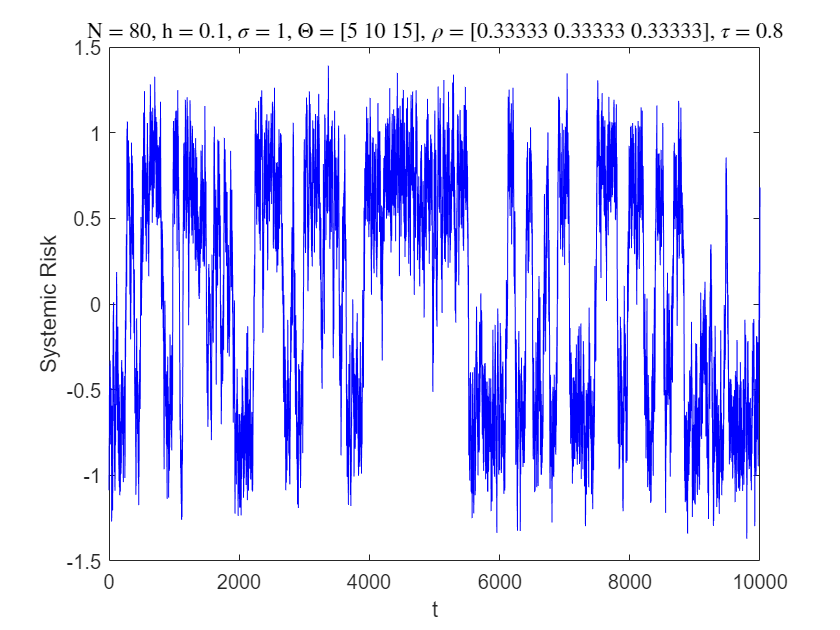

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$N = 120$:

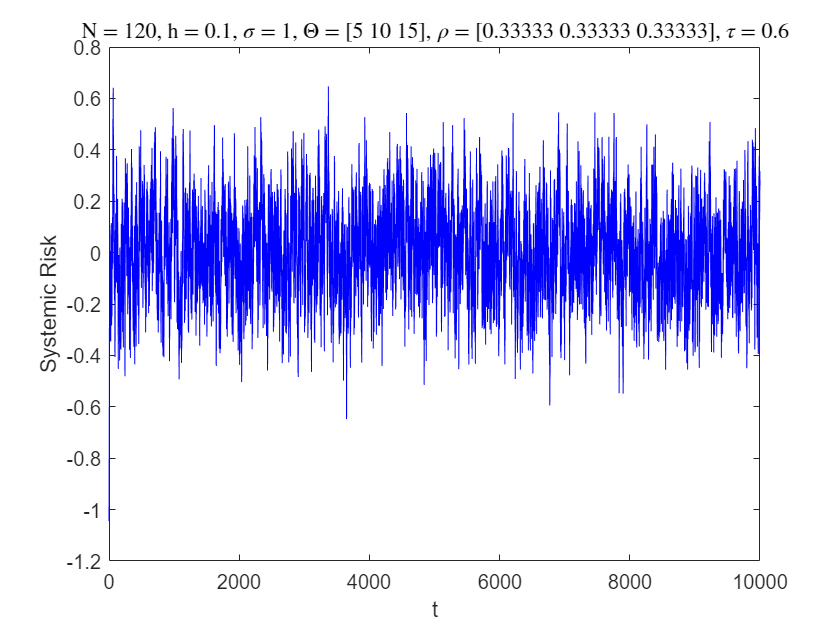

N = 120;

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

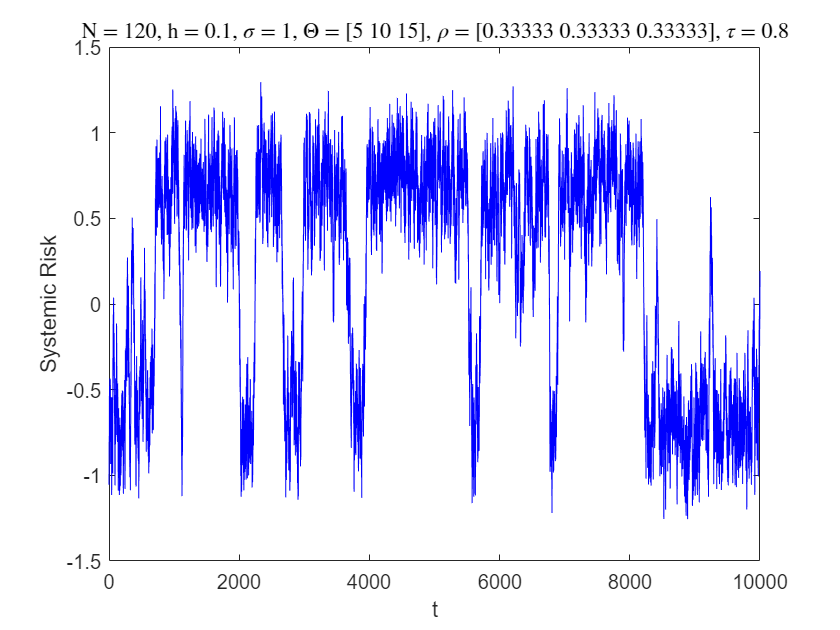

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$N = 160$:

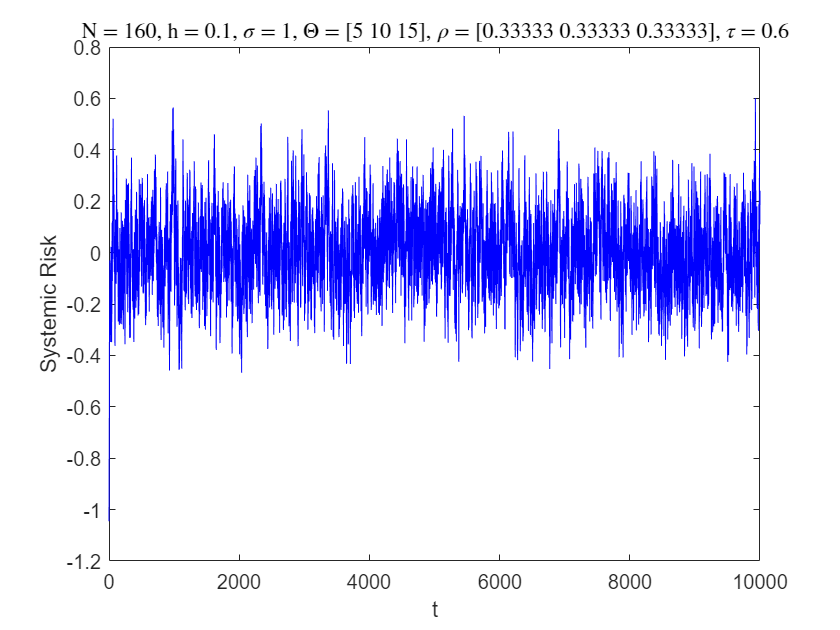

N = 160;

theta = [
    repelem(theta_l, 53, 1);
    repelem(theta_m, 54, 1);
    repelem(theta_h, 53, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

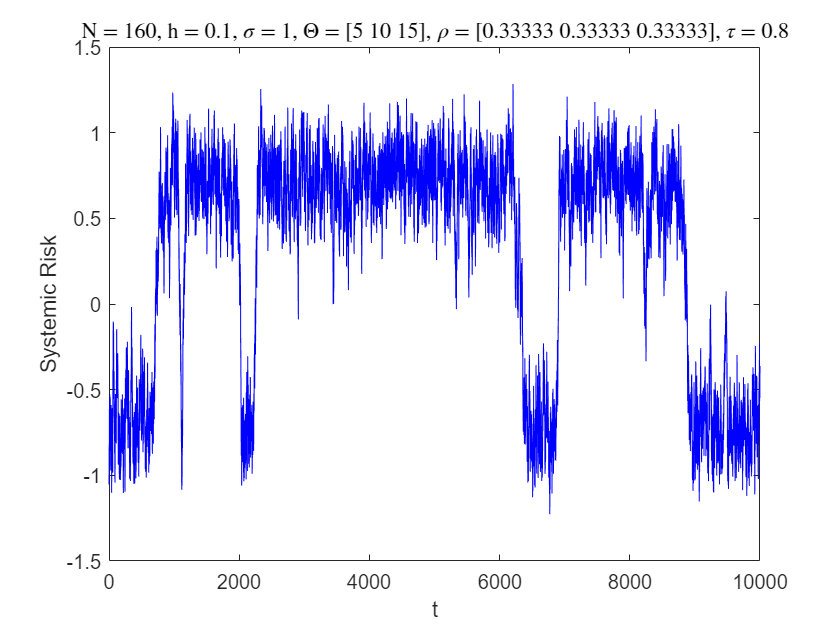

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

### Varying $\Theta$

Increasing diversity tends to destabilize the system.

Fix $N, h, \sigma, \rho$:

N = 100;
h = 0.1;
sig = 1;
rho_l = 0.33; rho_m = 0.34; rho_h = 0.33;
rho = [rho_l; rho_m; rho_h];

tau_low = 0.6;
tau_high = 0.8;

$\Theta = [10; 10; 10]$: Two stable equilibria

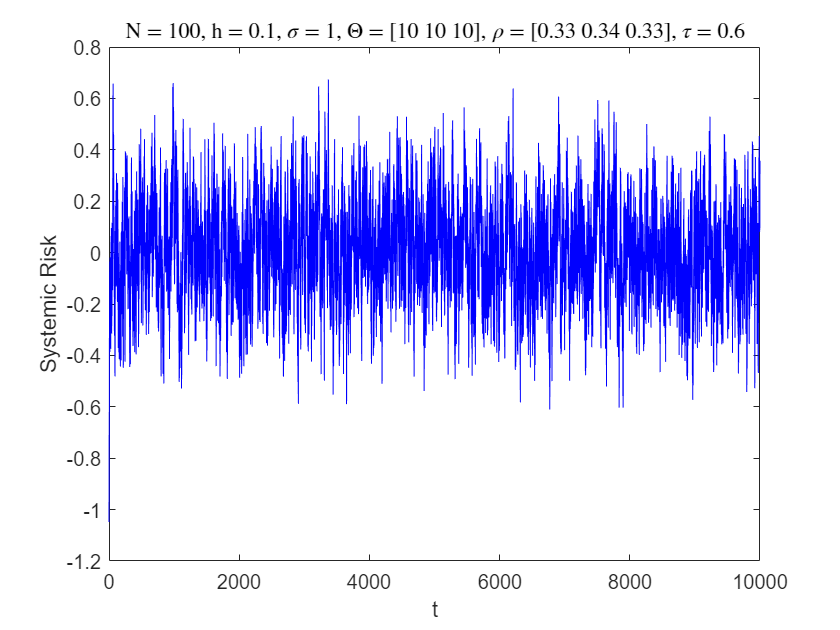

theta_l = 10; theta_m = 10; theta_h = 10;
Theta = [theta_l; theta_m; theta_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

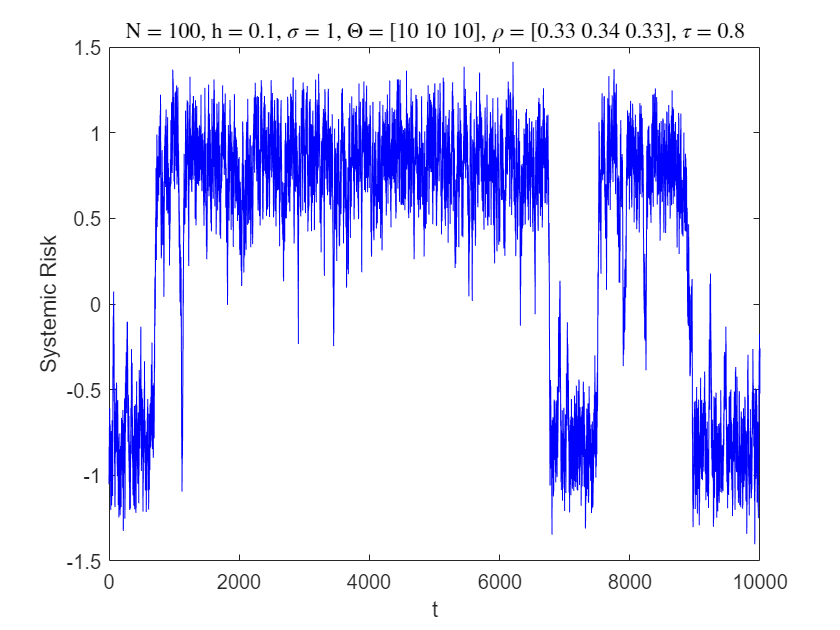

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$\Theta = [6;10;14]$: Two stable equilibria

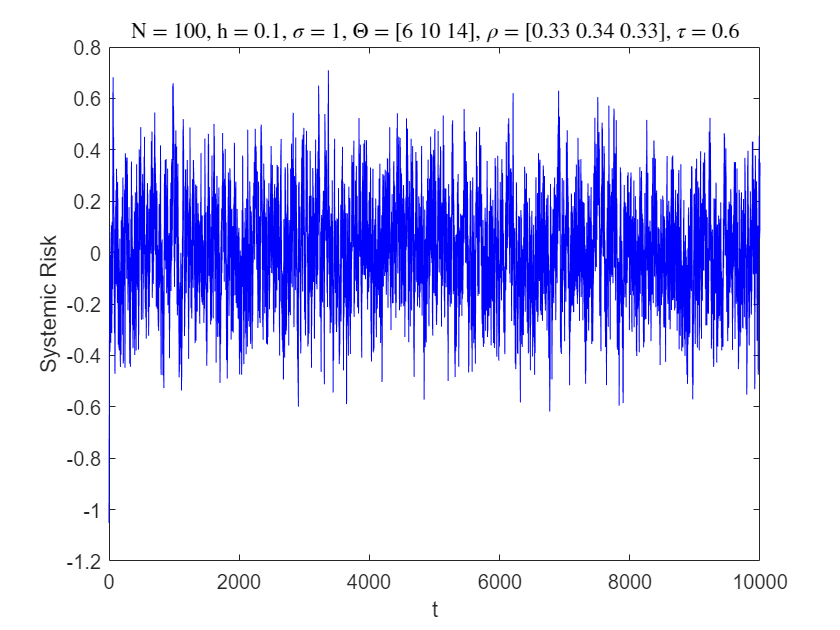

theta_l = 6; theta_m = 10; theta_h = 14;
Theta = [theta_l; theta_m; theta_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

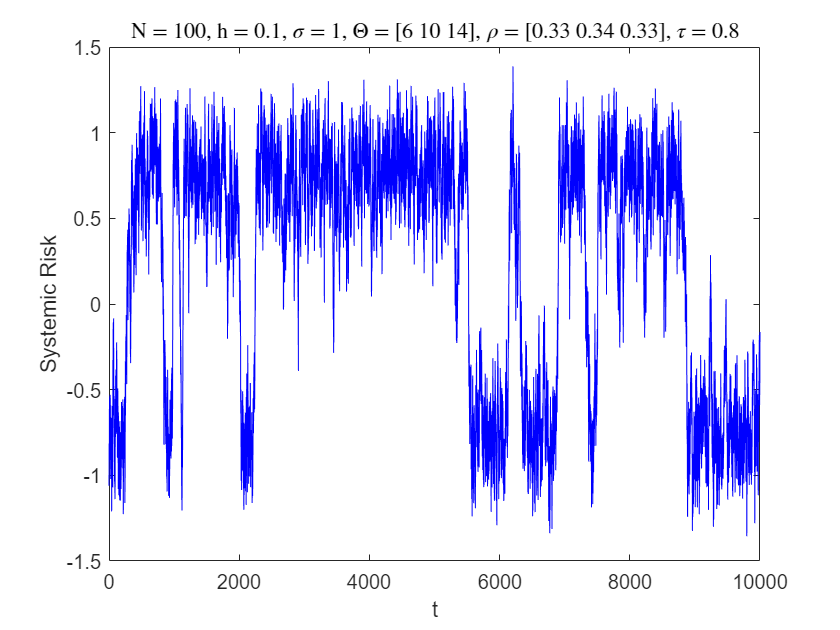

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$\Theta = [2;10;18]$: Two stable equilibria

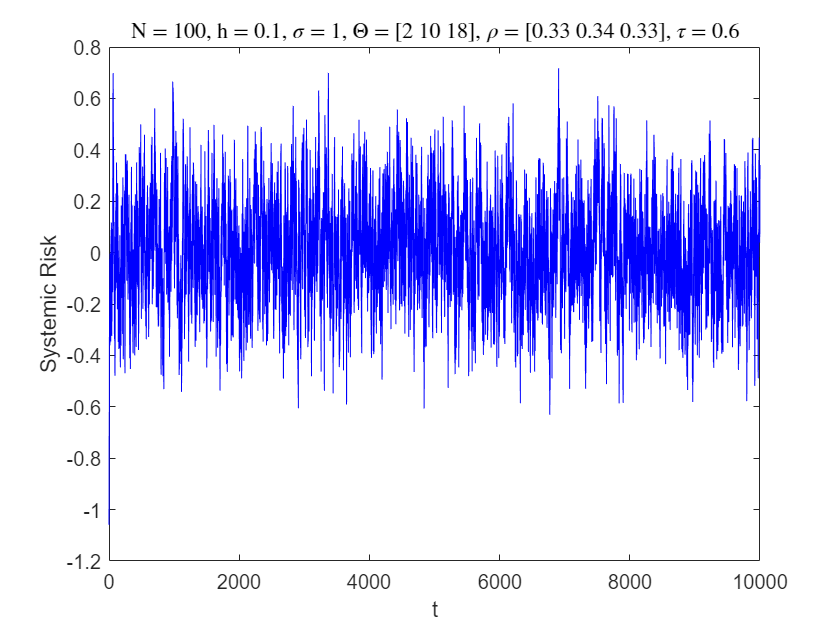

theta_l = 2; theta_m = 10; theta_h = 18;
Theta = [theta_l; theta_m; theta_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

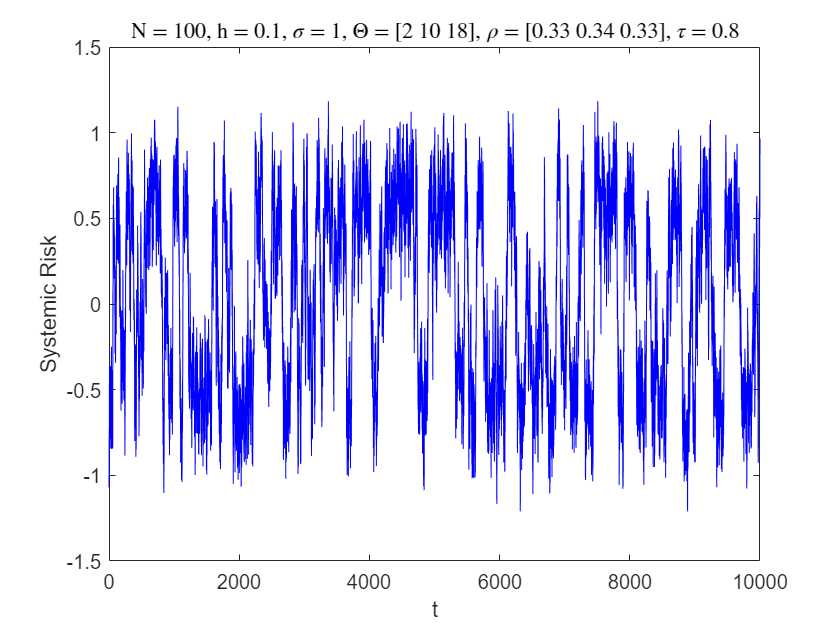

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

### Varying $\rho$

Increasing diversity tends to destabilize the system.

Fix $N, h, \sigma, \Theta$:

N = 100;
h = 0.1;
sig = 1;
theta_l = 5; theta_m = 10; theta_h = 15;
Theta = [theta_l; theta_m; theta_h];

tau_low = 0.6;
tau_high = 0.8;

$\rho = [0.1; 0.8; 0.1]$: Two stable equilibria

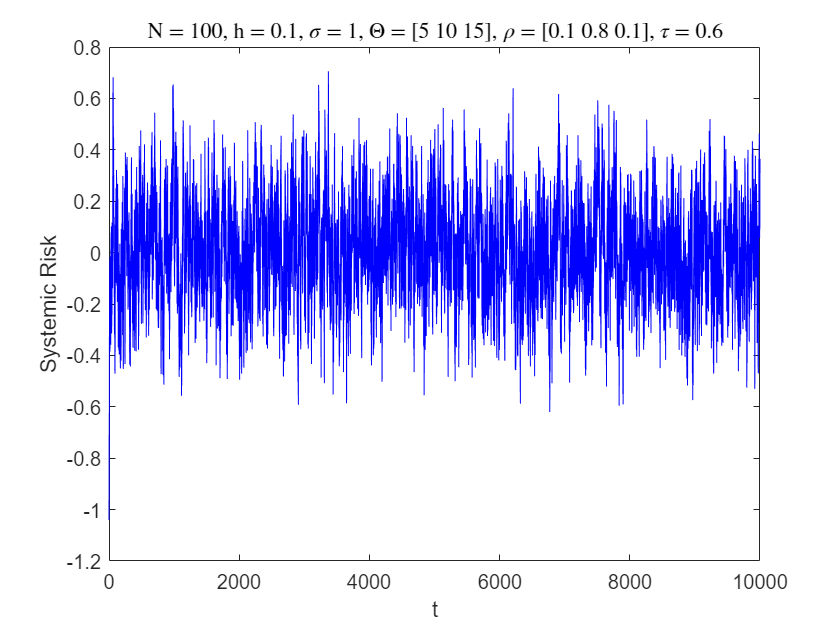

rho_l = 0.1; rho_m = 0.8; rho_h = 0.1;
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

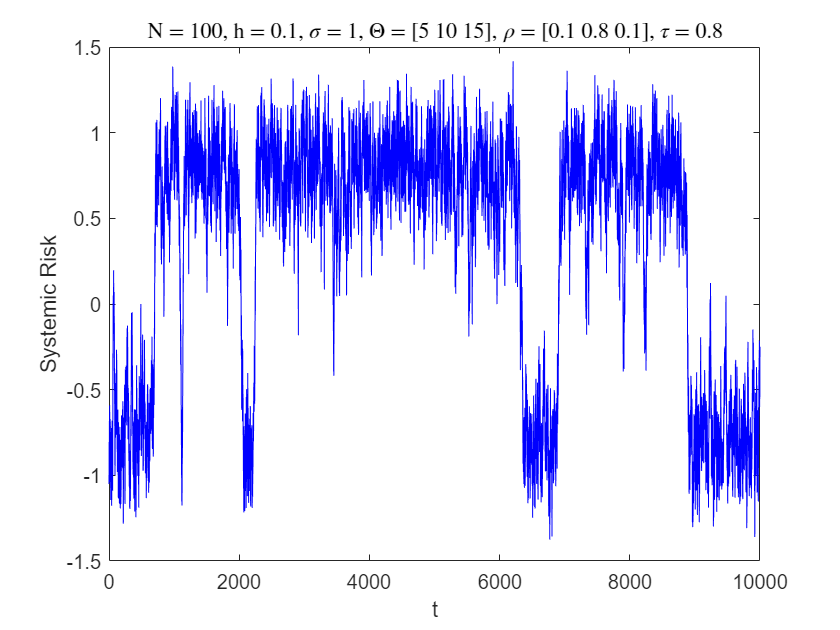

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$\rho = [0.3; 0.4; 0.3]$: Two stable equilibria

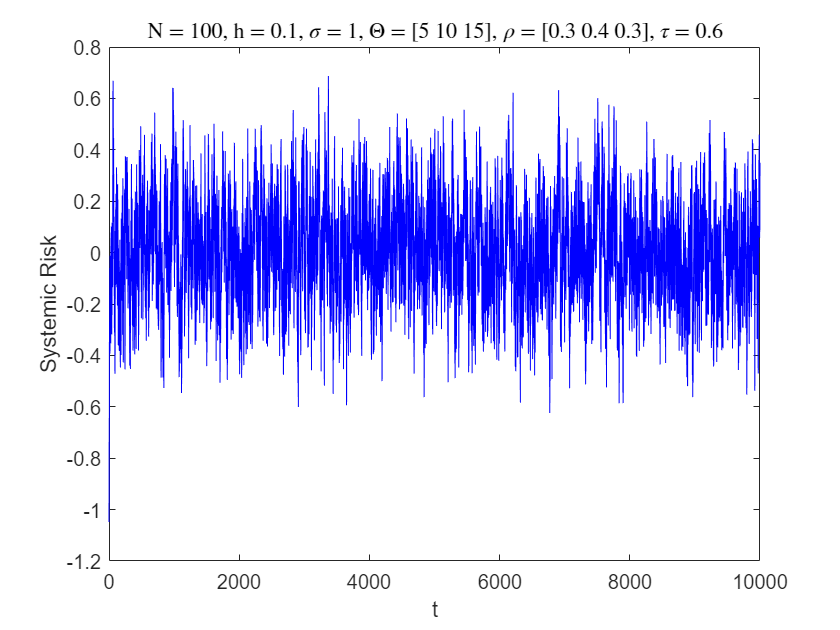

rho_l = 0.3; rho_m = 0.4; rho_h = 0.3;
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

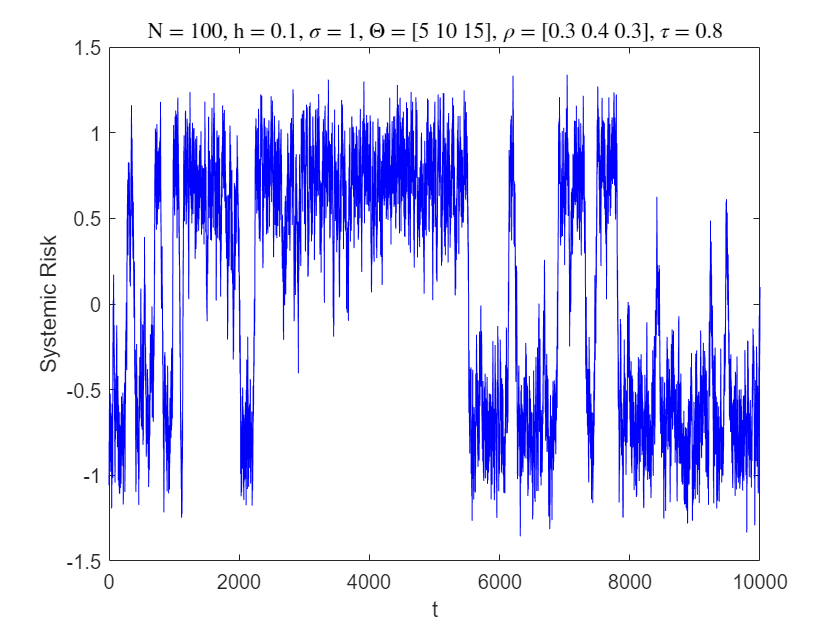

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

$\rho = [0.45; 0.1; 0.45]$: Two stable equilibria

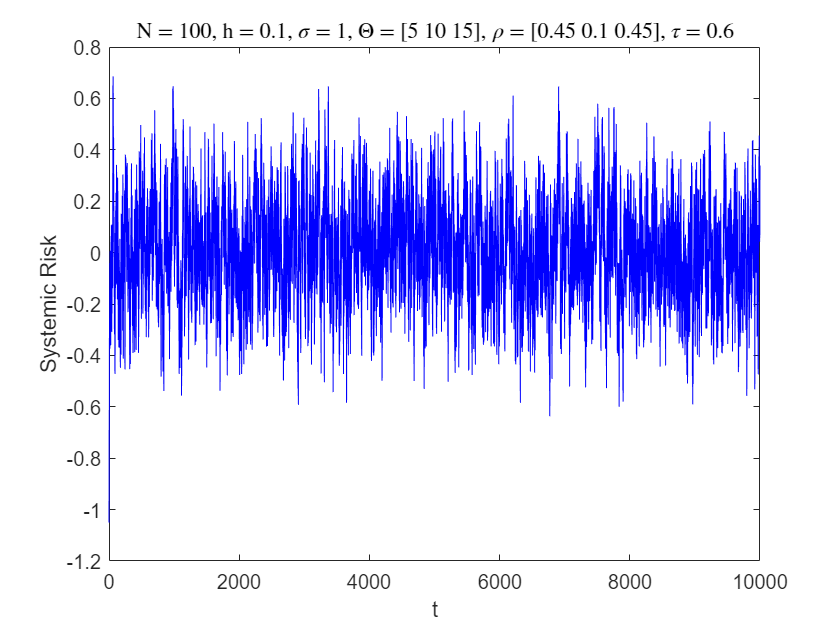

rho_l = 0.45; rho_m = 0.1; rho_h = 0.45;
rho = [rho_l; rho_m; rho_h];

theta = [
    repelem(theta_l, rho_l * N, 1);
    repelem(theta_m, rho_m * N, 1);
    repelem(theta_h, rho_h * N, 1)
    ];

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_low);

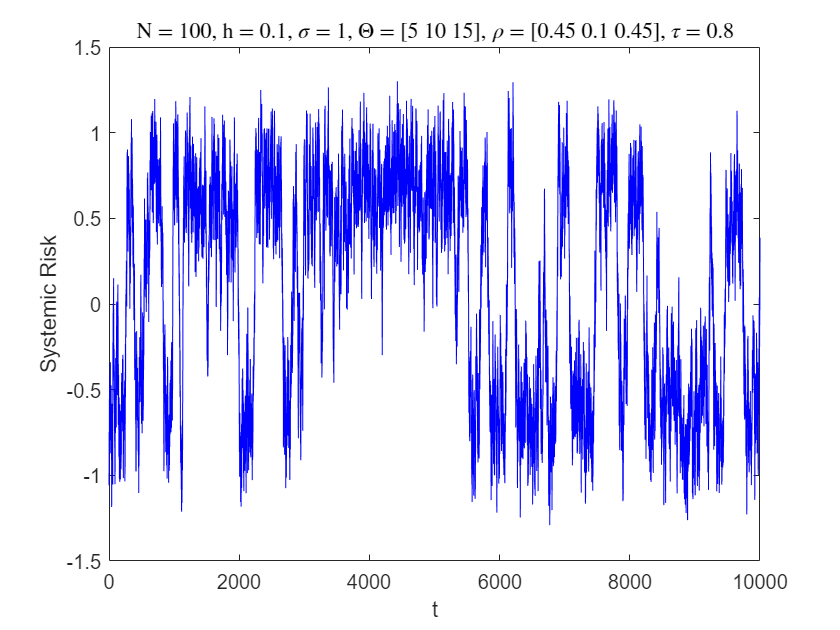

SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, tau_high);

Thresholding

compute_f(x) = $\frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right)$

function fvalues = compute_f(x, threshold)
    
    % Adjacency matrix
    % Agents interact if the distance between them is below the threshold

    % Compute the pairwise distances between x
    D = pdist2(x, x);
    % The adjacency matrix applies thresholding to the distance matrix
    A = D;
    % Samples that are close together still interact
    A(D <= threshold) = 1;
    % Samples that are far from each other stop interacting
    A(D > threshold) = 0;


    % Computes f(x) given an adjacency matrix A

    N = length(x);
    fvalues = zeros(N, 1);

    % Compute f(x_{j}) for j = 1,...,N
    for j = 1:N
        fvalues(j) = 1/N .* A(j, :) * (x - x(j));            
    end

end


$$f(t, x) = -h U\left(x_{j}(t)\right) + \theta \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right)$$


function SolveHomogeneousSDE(t, N, h, sig, theta, threshold)
    
    % Define SDE
    x0 = -1 + zeros(N, 1);
    U = @(y) y.^3 - y;
    f = @(t, x) -h.*U(x) + theta.* compute_f(x, threshold); 
    g = @(t, x) sig;    
   
    % Use Euler-Maruyama to solve SDE
    opts = sdeset('RandSeed', 1);
    x = sde_euler(f, g, t, x0, opts); 
    xbar = mean(x, 2);

    % Plot
    figure; 
    plot(t, xbar, 'b');
    title(['N = ' num2str(N) ',' ...
        ' h = ' num2str(h) ',' ...
        ' $\sigma$ = ' num2str(sig) ',' ...
        ' $\theta$ = ' num2str(theta(:).') ',' ...
        ' $\tau$ = ' num2str(threshold)], ...
    "Interpreter", "latex");
    xlabel('t'); ylabel('Systemic Risk');

end

Heterogeneous agents


$$f(t, x) = -h U\left(x_{j}(t)\right) + \theta_{j} \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right)$$


function SolveHeterogeneousSDE(t, N, h, sig, theta, Theta, rho, threshold)
    
    % Define SDE
    x0 = -1 + zeros(N, 1);
    U = @(y) y.^3 - y;
    f = @(t, x) -h.*U(x) + theta.*compute_f(x, threshold); 
    g = @(t, x) sig;        

    % Use Euler-Maruyama to solve SDE
    opts = sdeset('RandSeed', 1);
    x = sde_euler(f, g, t, x0, opts);
    xbar = mean(x, 2);  
    
    % Plot
    figure; 
    plot(t, xbar, 'b');
    title(['N = ' num2str(N) ',' ...
        ' h = ' num2str(h) ',' ...
        ' $\sigma$ = ' num2str(sig) ',' ...
        ' $\Theta$ = [' num2str(Theta(:).') '],' ...
        ' $\rho$ = [' num2str(rho(:).') '],' ...
        ' $\tau$ = ' num2str(threshold)], ...
    "Interpreter", "latex");
    xlabel('t'); ylabel('Systemic Risk');
    
end